clc
clear

# **Projeto Final - Circuitos Elétricos II**

## **Circuito No Tempo**

**Grupo 07:**

- Miguel Marques Ferreira - 20180080112

- Pedro Henrique Garcia  -  20190112775

- Maria Stefanie Moura    -  20180085530

- Gabriel Bordini Lira    -     20180092570

## Dados de Entrada

dados_entrada = readtable('./tabela_de_entrada_grupo_07_c2.csv')

dados_entrada = 3×14 table
    Ramo    n_Sa_da    n_Chegada    R_Ohm_    L_H_    I0_A_    C_F_    V0_V_    Tipo_Fonte_de_Tens_o    Vind_V_    Fase_V_rad_    Iind_A_    Fase_I_rad_    W_rad_s_
    ____    _______    _________    ______    ____    _____    ____    _____    ____________________    _______    ___________    _______    ___________    ________

     1         1           2          2          0      0       0        0               0                10            0            0            0            8    
 

### Informações

#### Número de Ramos

numero_de_ramos = size(dados_entrada.Ramo);
numero_de_ramos = numero_de_ramos(1)

numero_de_ramos = 3

#### Número de Nós

aux1 = max(dados_entrada.n_Sa_da);
aux2 = max(dados_entrada.n_Chegada);

if aux1 > aux2
    numero_de_nos = aux1(1);
else
    numero_de_nos = aux2(1);
end

numero_de_nos

numero_de_nos = 2

#### Variáveis Simbólicas

syms s
syms t

#### Frequência

frequencia_angular = dados_entrada.W_rad_s_;

#### Colunas do Arquivo (número e nome da coluna)

- Ramo

- Nó de Saída

- Nó de Entrada

- Resistência de Ramo

- Indutância de Ramo

- Corrente Inicial do Indutor

- Capacitância de Ramo

- Tensão Inicial do Capacitor

- Tipo de Fonte (não é utilizado)

- Fonte de Tensão de Ramo

- Fase da Fonte de Tensão de Ramo

- Fonte de Corrente de Ramo

- Fase da Fonte de Corrente de Ramo

- Frequência Angular

## Formando as Matrizes

### Matriz de Incidência

matriz_de_incidencia = zeros(numero_de_nos,numero_de_ramos);
entrada_e_saida = dados_entrada(:,(2:3));
entrada_e_saida;
for row = 1:numero_de_ramos
    
    entrada_saida = entrada_e_saida(row,:);
    matriz_de_incidencia(entrada_saida.(1),row) = 1;
    matriz_de_incidencia(entrada_saida.(2),row) = -1;
    
end
matriz_de_incidencia

matriz_de_incidencia =      1     1     1
    -1    -1    -1


matriz_de_incidencia_T = transpose(matriz_de_incidencia)

matriz_de_incidencia_T =      1    -1
     1    -1
     1    -1


### Matriz de Incidência Reduzida

matriz_de_incidencia_red = matriz_de_incidencia((1:(end-1)),:);
matriz_de_incidencia_red_T = transpose(matriz_de_incidencia_red)

matriz_de_incidencia_red_T =      1
     1
     1


### Matriz de Admitâncias

#### Equivalente de Laplace

resistencias_s = dados_entrada.R_Ohm_;
capacitancias = dados_entrada.C_F_;
indutancias = dados_entrada.L_H_;

% Laplace
capacitancias_s = 1./(s*capacitancias);
capacitancias_s(capacitancias_s(:) == Inf) = 0 %tratando a exceção de divisão por zero e adicionando...

$$capacitancias\_s = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

% zero caso o elemento passado seja nulo.
indutancias_s = s.*indutancias;

#### Matriz de Impedâncias

matriz_de_admitancias = zeros(numero_de_ramos,numero_de_ramos);
impedancia_equivalente = resistencias_s + indutancias_s + capacitancias_s;
admitancias = 1./impedancia_equivalente(:);
matriz_de_admitancias = diag(admitancias)

$$matriz\_de\_admitancias = \left(\begin{array}{ccc} \frac{1}{2} & 0 & 0\\ 0 & \frac{1}{\frac{s}{4}+1} & 0\\ 0 & 0 & \frac{1}{\frac{s}{4}+4} \end{array}\right)$$

### Fn - Admitância de Nó

Fn = (matriz_de_incidencia_red*matriz_de_admitancias)*matriz_de_incidencia_red_T

$$Fn = \frac{1}{\frac{s}{4}+1}+\frac{1}{\frac{s}{4}+4}+\frac{1}{2}$$

### Vs - Fontes de Tensão Independentes

Vs = dados_entrada.Vind_V_.*cos(frequencia_angular*t + (pi/180).*dados_entrada.Fase_V_rad_)

$$Vs = \left(\begin{array}{c} 10\,\cos\left(8\,t\right)\\ 0\\ 0 \end{array}\right)$$

Vs = laplace(Vs) + dados_entrada.L_H_.*dados_entrada.I0_A_ - (1/s).*dados_entrada.V0_V_

$$Vs = \left(\begin{array}{c} \frac{10\,s}{s^{2}+64}\\ 0\\ 0 \end{array}\right)$$

### Js - Fontes de Corrente Independentes

Js = dados_entrada.Iind_A_.*cos(frequencia_angular*t + dados_entrada.Fase_I_rad_)

$$Js = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Js = (1/s).*dados_entrada.Iind_A_ + laplace(Js)

$$Js = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

### Is - Correntes

Is = matriz_de_incidencia_red*matriz_de_admitancias*Vs - matriz_de_incidencia_red*Js

$$Is = \frac{5\,s}{s^{2}+64}$$

### e - Tensão de Nó

e = inv(Fn)*Is

$$e = \frac{5\,s}{\left(s^{2}+64\right)\,\left(\frac{1}{\frac{s}{4}+1}+\frac{1}{\frac{s}{4}+4}+\frac{1}{2}\right)}$$

### V - Tensão de Ramo

V = matriz_de_incidencia_red_T*e

$$V = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,s}{\left(s^{2}+64\right)\,\left(\frac{1}{\frac{s}{4}+1}+\frac{1}{\frac{s}{4}+4}+\frac{1}{2}\right)} \end{array}$$

### J - Corrente de Ramo

J = Js + matriz_de_admitancias*V - matriz_de_admitancias*Vs

$$J = \begin{array}{l} \left(\begin{array}{c} \frac{5\,s}{2\,\left(s^{2}+64\right)\,\sigma_{1}}-\frac{5\,s}{s^{2}+64}\\ \frac{5\,s}{\left(\frac{s}{4}+1\right)\,\left(s^{2}+64\right)\,\sigma_{1}}\\ \frac{5\,s}{\left(\frac{s}{4}+4\right)\,\left(s^{2}+64\right)\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\frac{s}{4}+1}+\frac{1}{\frac{s}{4}+4}+\frac{1}{2} \end{array}$$

## Aplicando a Transformada de Laplace Inversa

#### Tensão de Ramo no Tempo

V_tempo = ilaplace(V)

$$V\_tempo = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{225\,\cos\left(8\,t\right)}{53}+{\mathrm{e}}^{-8\,t}+\frac{252\,{\mathrm{e}}^{-28\,t}}{53}-\frac{125\,\sin\left(8\,t\right)}{53} \end{array}$$

#### Tensão de Nó no Tempo

e_tempo = ilaplace(e)

$$e\_tempo = \frac{225\,\cos\left(8\,t\right)}{53}+{\mathrm{e}}^{-8\,t}+\frac{252\,{\mathrm{e}}^{-28\,t}}{53}-\frac{125\,\sin\left(8\,t\right)}{53}$$

#### Corrente de Ramo no Tempo

J_tempo = ilaplace(J)

$$J\_tempo = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-\frac{305\,\cos\left(8\,t\right)}{106}+\frac{126\,{\mathrm{e}}^{-28\,t}}{53}-\frac{125\,\sin\left(8\,t\right)}{106}\\ \frac{95\,\cos\left(8\,t\right)}{53}-{\mathrm{e}}^{-8\,t}-\frac{42\,{\mathrm{e}}^{-28\,t}}{53}+\frac{65\,\sin\left(8\,t\right)}{53}\\ \frac{115\,\cos\left(8\,t\right)}{106}+\sigma_{1}-\frac{84\,{\mathrm{e}}^{-28\,t}}{53}-\frac{5\,\sin\left(8\,t\right)}{106} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{-8\,t}}{2} \end{array}$$

## Gráficos

tmin = 0;
tmax = 3;
npt = 100;

h = (tmax - tmin)/npt; % passo de cálculo

time = tmin:h:tmax - h; % vetor tempo de simulação

#### Tensão no Resistor de 2 Ohm

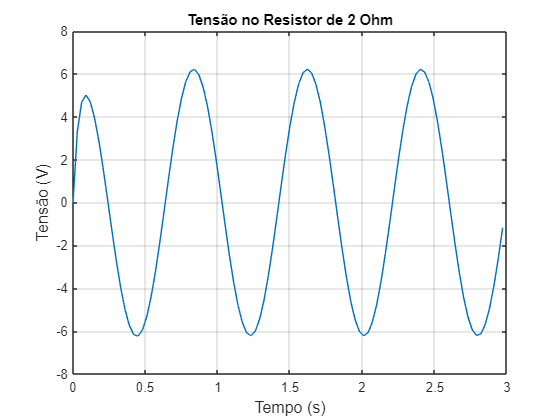

vr = subs((10*cos(8*t) - V_tempo(1)), t, time); % tensão vs(t)

figure(1), plot(time, vr);

xlabel("Tempo (s)", "FontSize", 12);
ylabel("Tensão (V)", "FontSize", 12);
title 'Tensão no Resistor de 2 Ohm';
grid on;    

### Corrente no Resistor de 2 Ohm

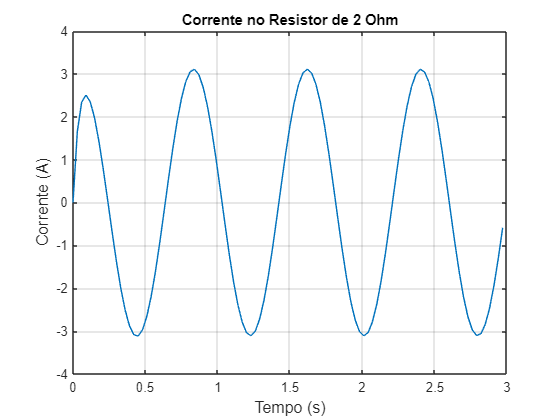

ir = subs(-J_tempo(1), t, time);

figure(1), plot(time, ir);

xlabel("Tempo (s)", "FontSize", 12);
ylabel("Corrente (A)", "FontSize", 12);
title 'Corrente no Resistor de 2 Ohm';
grid on;

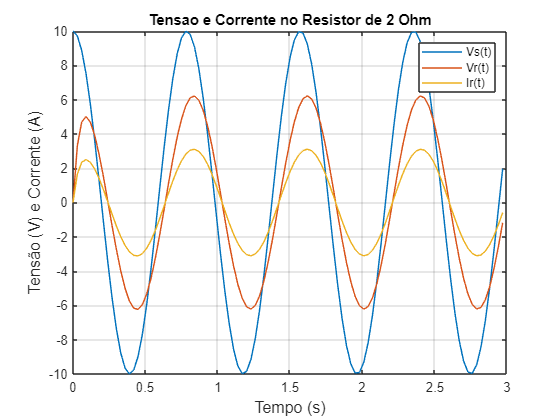

vr = subs((10*cos(8*t) - V_tempo(1)), t, time);
tensao_alimentacao = subs(10*cos(8*t),t,time);

figure(1);
plot(time, tensao_alimentacao, time, vr, time, ir);

xlabel("Tempo (s)", "FontSize", 12);
ylabel("Tensão (V) e Corrente (A)", "FontSize", 12);
legend ('Vs(t)','Vr(t)','Ir(t)');
title 'Tensao e Corrente no Resistor de 2 Ohm';
grid on; 

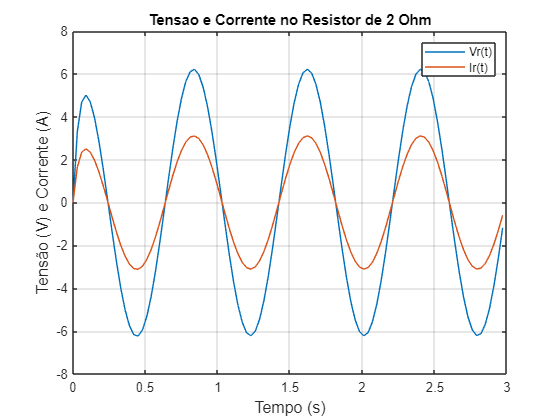

vr = subs((10*cos(8*t) - V_tempo(1)), t, time);

figure(1);
plot(time, vr, time, ir);

xlabel("Tempo (s)", "FontSize", 12);
ylabel("Tensão (V) e Corrente (A)", "FontSize", 12);
legend ('Vr(t)','Ir(t)');
title 'Tensao e Corrente no Resistor de 2 Ohm';
grid on; 